# Classical Multidimensional Scaling

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and displays the data.

X = readmatrix("./data/X.csv");
whos X

  Name        Size            Bytes  Class     Attributes

  X         124x4              3968  double              



## Task 1

The matrix `X` has 4 columns, and therefore would be best visualized using 4 dimensions. In this activity, you will use multidimensional scaling to visualize the data using fewer dimensions, while retaining most of the information it contains.

To perform multidimensional scaling, you must first calculate the pairwise distances between observations. You can use the `pdist` function to calculate these distances.

`distances` `=` `pdist``(``data``)``;`

D = pdist(X);

## Task 2

The `cmdscale` function finds a configuration matrix and its corresponding eigenvalues for a set of pairwise distances.

`[``configMat``,``eigVal``]` `=` `cmdscale``(``distances``)``;`

[Y, e] = cmdscale(D);

## Task 3

You can use the `pareto` function to create a Pareto chart, which visualizes relative magnitudes of a vector in descending order.

`pareto``(``vector``)`

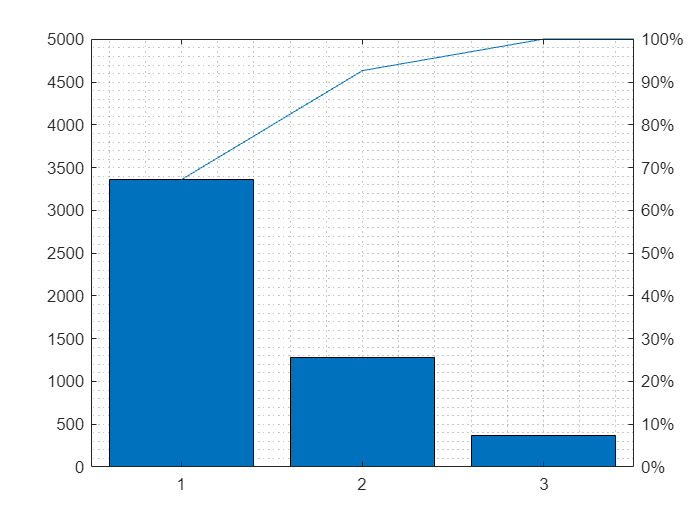

pareto(e)
grid minor

## Task 4

From the Pareto chart, you can see that over 90% of the distribution is described with just two variables.

You can use the `scatter` function to create a scatter plot of the first two columns of a matrix `M`.

`scatter``(``M``(``:,``1``)``,``M``(``:,``2``))`

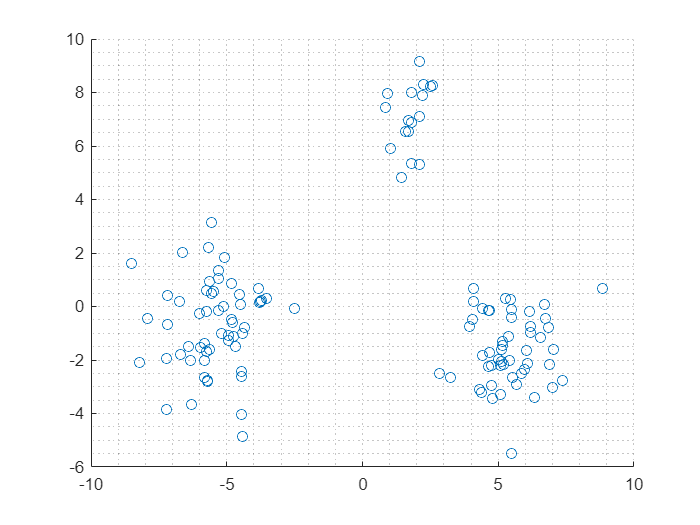

scatter(Y(:, 1), Y(:, 2))
grid minor

## Task 5

From the Pareto chart, notice that 100% of the distribution is described with three variables.

The `scatter3` function creates a three-dimensional scatter plot. You can use `scatter3` to create a scatter plot of three columns of a matrix `M`.

`scatter3``(``M``(``:,``1``)``,``M``(``:,``2``)``,``M``(``:,``3``))`

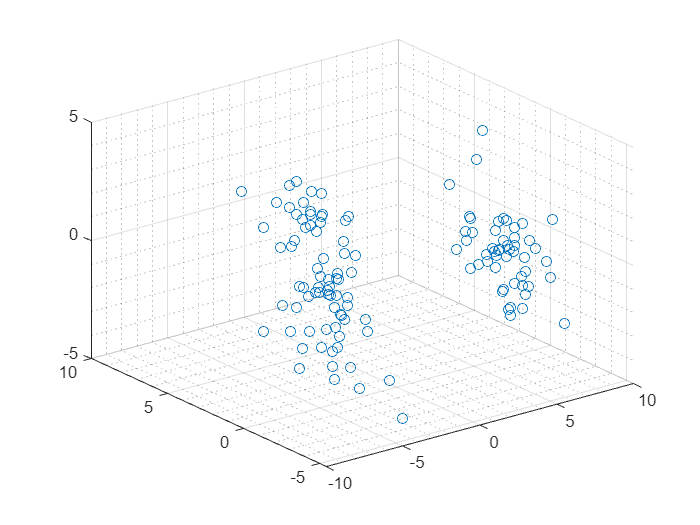

scatter3(Y(:, 1), Y(:, 2), Y(:, 3))
grid minor